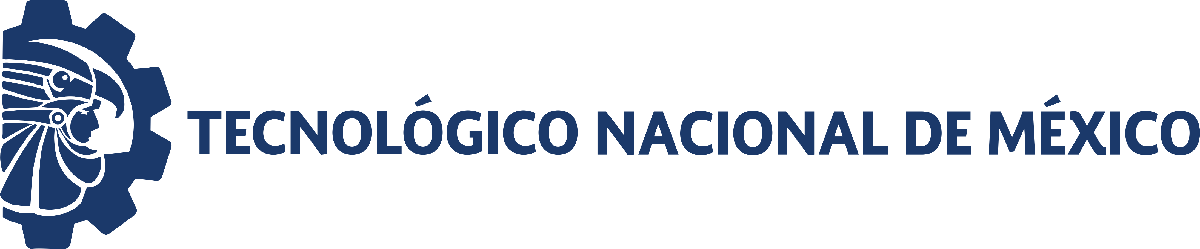                                 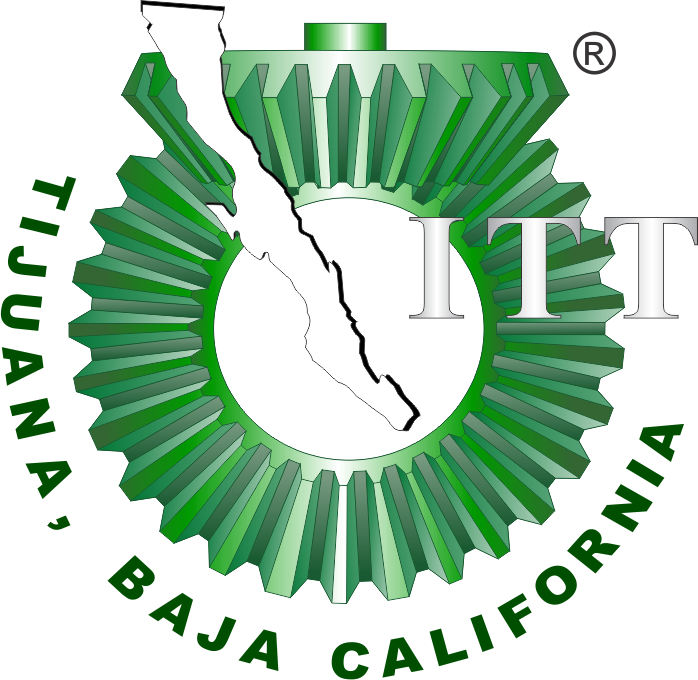

# Práctica: Regeneraciòn De Globulos Rojos   

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

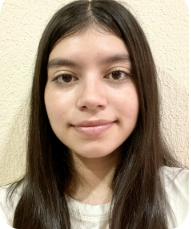

Nombre del alumno: MARIA CRISTINA LOPEZ LOPEZ

Número de control: 22212259

Correo institucional: l22212259**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all')
tend = 180; %tiempo de la simulacion en dias
dt = 1E-3; % intervalo de integracion para el metodo de soluciones por diferencias finitas
n = round(tend/dt); %cantidad de iteracciones para el metodo numerico 

%condiciones iniciales base para cada paciente 
x1_0 = 59; x2_0 = 44; x3_0 = 885;

%parametros particulares para cada paciente 
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22212259; %semilla para asegurar reproducibilidad
rng(seed,'twister')
%intervalo de las condiciones iniciales 
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%condiciones iniciales para cada paciente 
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0');

x1(0) = 
   59.1630   58.7785   59.5551   58.7764   58.7537   59.4230   59.2951   58.4962   58.5228   59.0685



x2(0) = 
   44.1216   43.8348   44.4140   43.8333   43.8163   44.3155   44.2201   43.6243   43.6441   44.0511



x3(0) = 
  887.4453  881.6781  893.3272  881.6464  881.3060  891.3455  889.4266  877.4431  877.8418  886.0270



## Caso :  Sin transfusion sanguinea [u(t)=0]

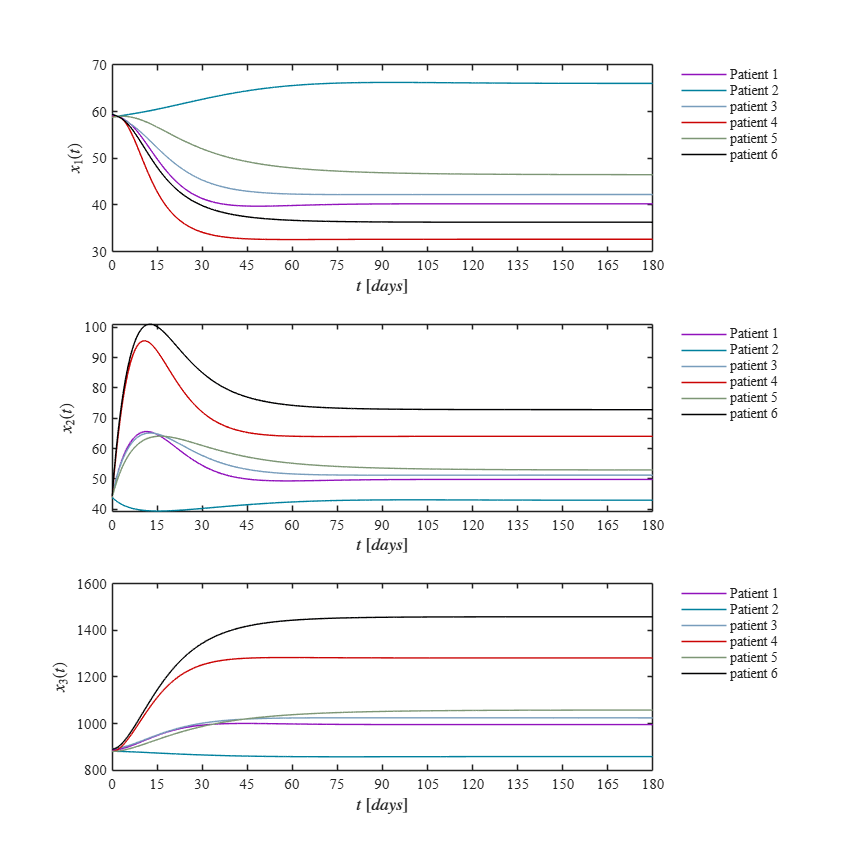

u=zeros(n+1,1);
fig = 1;
for i = 1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## caso : Sin transfusion sanguinea


$$\overset{\ldotp }{x_1 } =\beta \left(x_0 -k_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$
 


$$\overset{\ldotp }{x_2 } =\beta \left(k_1 x_1 -k_2 x_2 \right)\;$$



$$\overset{\ldotp }{x_3 } =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3 \;$$


## Caso :  Con transfusion sanguinea [u(t)=1 [t1,t2]]

u=zeros(n+1,1);
for i=1:1000
    u(i)=1;
end
fig = 2;
for i = 1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)

end

function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)

%parametros fijos del sistema 
Base = 885.42; X0=7.3785; K1=0.125; K2=0.1667; alpha=0.00833;
t = (0:dt:tend)';
n = round(tend/dt);
x1 = zeros(n+1,1); x1(1) = x1_0;
x2 = zeros(n+1,1); x2(1) = x2_0;
x3 = zeros(n+1,1); x3(1) = x3_0;

    for i = 1:n
        x1(i+1) = x1(i) + (beta*(X0 - K1*x1(i))+ gamma*(Base - x3(i))*(1-u(i))*x1(i)/Base)*dt;
        x2(i+1)= x2(i) + (beta*K1*x1(i)-K2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(K2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;

    end

end

## Funcion : Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)

    set(figure(fig), 'color', 'w')
    set(gcf, 'Units','Centimeters','position',[1,1,20,20])
        mycolors = [145,18,188;
                0,128,157;
                120,157,188;
                203,4,4;
                125,150,117;
                0,0,1;
                255,143,143;
                255,241,203;
                194,226,250;
                183,163,227]/255; 

              
    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L=legend('Patient 1','Patient 2','patient 3','patient 4','patient 5',...
        'patient 6','patient 7','pàtient 8','patient 9','patient 10');
    set(L,'FontSize',9,'Box','off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
   set(gca,'FontName','Times New Roman','Fontsize',10)
  L=legend('Patient 1','Patient 2','patient 3','patient 4','patient 5',...
        'patient 6','patient 7','pàtient 8','patient 9','patient 10');
    set(L,'FontSize',9,'Box','off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L=legend('Patient 1','Patient 2','patient 3','patient 4','patient 5',...
        'patient 6','patient 7','pàtient 8','patient 9','patient 10');
    set(L,'FontSize',9,'Box','off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)
    set(gca,'FontName','Times New Roman','FontSize',10)

    if fig == 1
        exportgraphics(gcf,'Caso sin transfucion.pdf','ContentType','Vector')
    elseif fig == 2
        exportgraphics(gcf,'Caso Con transfucion.pdf','ContentType','Vector')
    end
end